# Measuring Instruments

clear; clc; close all;

syms r zeta 

x_amplitude = sqrt((1 + (2*zeta*r)^2)/((1-r^2)^2 + (2*zeta*r)^2))

$$x\_amplitude = \sqrt{\frac{4\,r^{2}\,\zeta^{2}+1}{4\,r^{2}\,\zeta^{2}+{\left(r^{2}-1\right)}^{2}}}$$

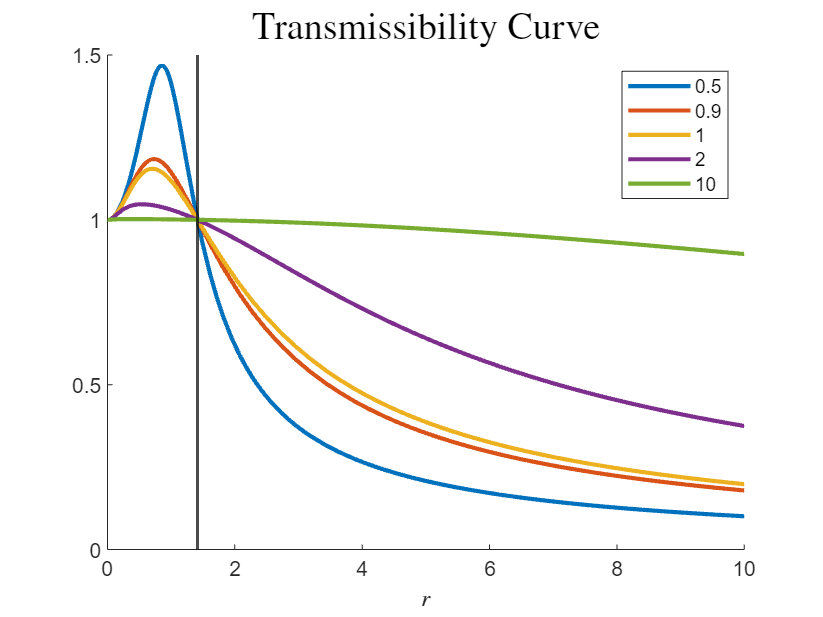

zeta_array = [ 0.5, 0.9, 1, 2, 10] ;
figure; hold on;
for i = 1:length(zeta_array)
    fplot(subs(x_amplitude, zeta, zeta_array(i)), [0, 10], LineWidth=2);
end

% xline(1);
% yline(1);
xline(sqrt(2), 'k', LineWidth=1.5)
xlabel("$r$", Interpreter="latex");
title("Transmissibility Curve", FontSize=18, Interpreter="latex")
legend("0.5", "0.9", "1", "2", "10");

legend boxoff

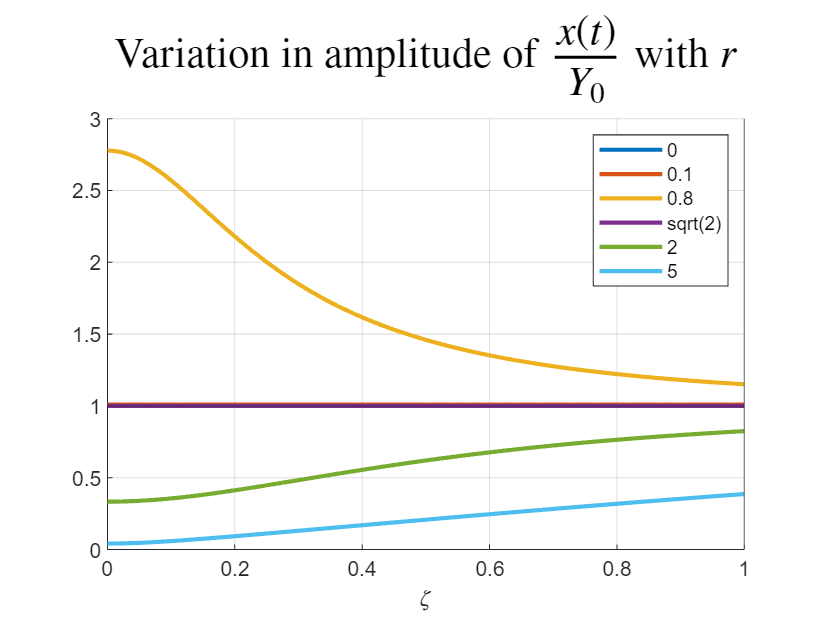

r_array = [0, 0.1, 0.8, sqrt(2), 2, 5] ;
figure; hold on;
for i = 1:length(r_array)
    fplot(subs(x_amplitude, r, r_array(i)), [0, 1], LineWidth=2);
end
grid on;
xline(1);
yline(1);
xlabel("$\zeta$", Interpreter="latex");
title("Variation in amplitude of $\frac{x(t)}{Y_0}$ with $r$", FontSize=20, Interpreter="latex")
legend("0", "0.1", "0.8", "sqrt(2)", "2", "5");

x_amplitude_zeta = simplifyFraction(diff(x_amplitude, zeta))

$$x\_amplitude\_zeta = -\frac{4\,r^{2}\,\zeta \,\left(2\,r^{2}-r^{4}\right)}{\sqrt{\frac{4\,r^{2}\,\zeta^{2}+1}{r^{4}+4\,r^{2}\,\zeta^{2}-2\,r^{2}+1}}\,{\left(r^{4}+4\,r^{2}\,\zeta^{2}-2\,r^{2}+1\right)}^{2}}$$

x_amplitude_zeta_num = numden(x_amplitude_zeta)         

$$x\_amplitude\_zeta\_num = -4\,r^{2}\,\zeta \,\left(2\,r^{2}-r^{4}\right)$$

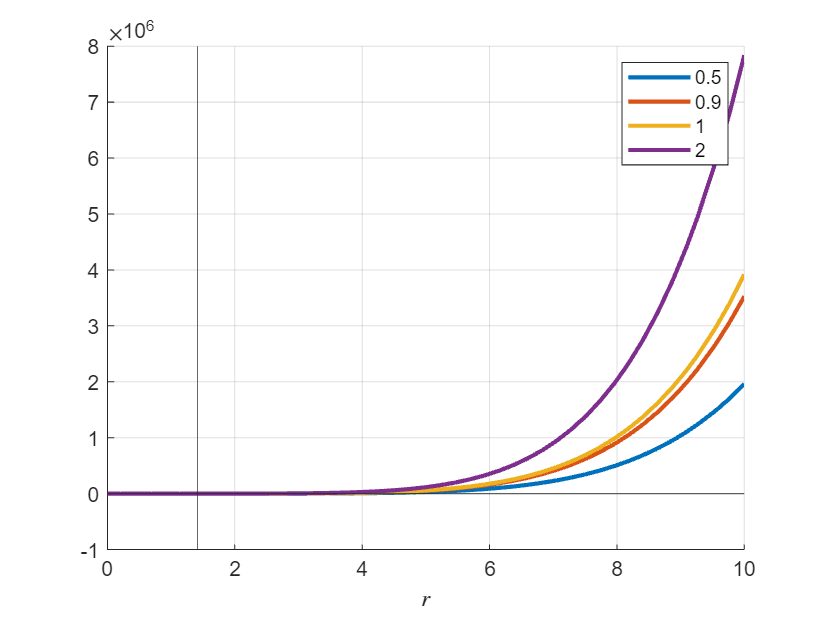

zeta_array = [ 0.5, 0.9, 1, 2] ;
figure; hold on;
for i = 1:length(zeta_array)
    fplot(subs(x_amplitude_zeta_num, zeta, zeta_array(i)), [0, 10], LineWidth=2);
end
grid on;
xline(sqrt(2));
yline(1);
xlabel("$r$", Interpreter="latex");
title("", FontSize=20, Interpreter="latex")
legend("0.5", "0.9", "1", "2");

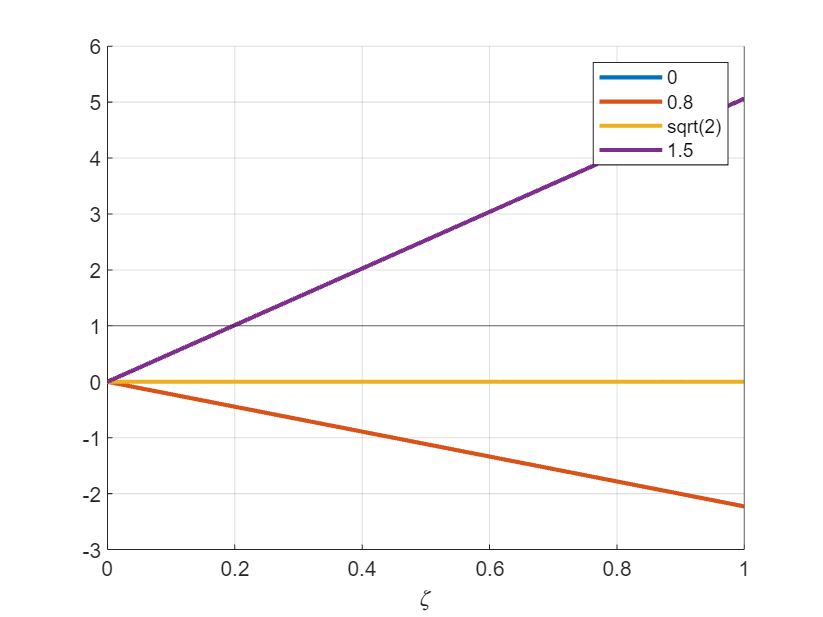

r_array = [0, 0.8, sqrt(2), 1.5] ;
figure; hold on;
for i = 1:length(r_array)
    fplot(subs(x_amplitude_zeta_num, r, r_array(i)), [0, 1], LineWidth=2);
end
grid on;
xline(1);
yline(1);
xlabel("$\zeta$", Interpreter="latex");
title("", FontSize=20, Interpreter="latex")
legend("0", "0.8", "sqrt(2)", "1.5");

x_phase = atan(2*zeta*r^3/(r^2 - 1 - 4*zeta^2*r^2))

$$x\_phase = -\mathrm{atan}\left(\frac{2\,r^{3}\,\zeta }{4\,r^{2}\,\zeta^{2}-r^{2}+1}\right)$$

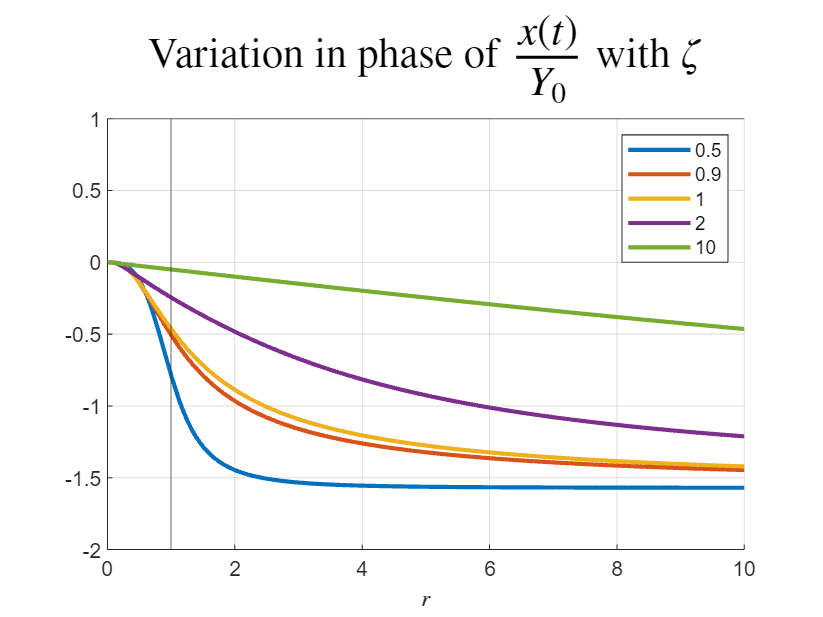

zeta_array = [ 0.5, 0.9, 1, 2, 10] ;
figure; hold on;
for i = 1:length(zeta_array)
    fplot(subs(x_phase, zeta, zeta_array(i)), [0, 10], LineWidth=2);
end
grid on;
xline(1);
yline(1);
xlabel("$r$", Interpreter="latex");
title("Variation in phase of $\frac{x(t)}{Y_0}$ with $\zeta$", FontSize=20, Interpreter="latex")
legend("0.5", "0.9", "1", "2", "10");

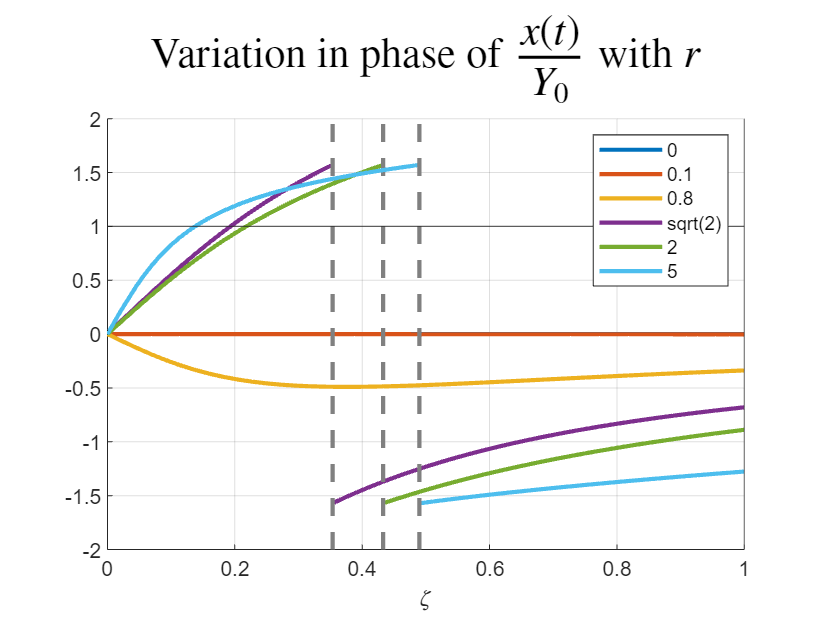

r_array = [0, 0.1, 0.8, sqrt(2), 2, 5] ;
figure; hold on;
for i = 1:length(r_array)
    fplot(subs(x_phase, r, r_array(i)), [0, 1], LineWidth=2);
end
grid on;
xline(1);
yline(1);
xlabel("$\zeta$", Interpreter="latex");
title("Variation in phase of $\frac{x(t)}{Y_0}$ with $r$", FontSize=20, Interpreter="latex")
legend("0", "0.1", "0.8", "sqrt(2)", "2", "5");

z_amplitude = r^2/sqrt((1-r^2)^2+(2*zeta*r)^2)

$$z\_amplitude = \frac{r^{2}}{\sqrt{4\,r^{2}\,\zeta^{2}+{\left(r^{2}-1\right)}^{2}}}$$

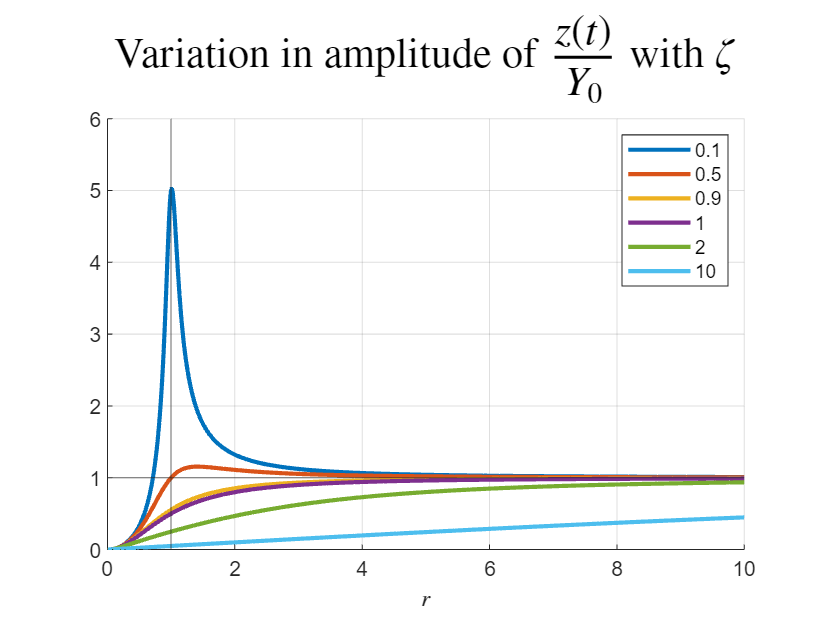

zeta_array = [ 0.1, 0.5, 0.9, 1, 2, 10] ;
figure; hold on;
for i = 1:length(zeta_array)
    fplot(subs(z_amplitude, zeta, zeta_array(i)), [0, 10], LineWidth=2);
end
grid on;
xline(1);
yline(1);
xlabel("$r$", Interpreter="latex");
title("Variation in amplitude of $\frac{z(t)}{Y_0}$ with $\zeta$", FontSize=20, Interpreter="latex")
legend("0.1", "0.5", "0.9", "1", "2", "10");